# 创建一个石墨烯TB模型并拟合参数

## 创建石墨烯TB模型(step by step)

- 声明一个空的模型；初始化其轨道数

Graphene = HR(2);

- 修改POSCAR格式

*generated by phonopy*

*   1.0*

*     2.4604399204208875    0.0000000000000000    0.0000000000000000*

*    -1.2302199602104438    2.1308034755698513    0.0000000000000000*

*     0.0000000000000000    0.0000000000000000   10.0000000000000000*

*C*

*   2*

*Direct*

*  0.6666666666666666  0.3333333333333333  0.0000000000000000 *`C p z `

*  0.3333333333333334  0.6666666666666667  0.0000000000000000 *`C p z`

- 导入POSCAR

Graphene = Graphene <'POSCAR_pz';
% Graphene = Graphene.input_orb_struct('POSCAR')
Graphene.orbL

ans =     0.6667    0.3333         0
    0.3333    0.6667         0


- 进行 nn_sk 搜索

- 这里 search_range 取 【1 1 0】，Accuracy 取小数点3位，maxR值取 5 埃

search_range = [1 1 0];
Accuracy = 3;
r_max_search = 5;
Graphene = Graphene.nn(search_range,Accuracy ,r_max_search);

Generating 2/2 th orb nn information ...
Giving nn_level for 32/32 th hopping  ...


- 可以简要获取一下这一步的信息，看下Rnn排名

[Rnn,~,~,~] = Graphene.nn_information();

- 这里我们取最近邻hopping

Graphene = Graphene.H_TBSK_gen('level_cut',1)

Generating Symbolic Hopping term ...< ok >
Setting NRPT 5/5 ...


Graphene =   HR - 属性:

        vectorL: [5×3 int32]
          HnumL: [2×2 double]
          HcoeL: [2×2×5 sym]
          NRPTS: 5
        WAN_NUM: 2
       Line_000: 1
      Basis_num: 2
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: VppP_1


- 查看一下体系的未知量（symbolic）

Graphene.symvar_list

$$ans = {\mathrm{VppP}}_{1}$$

## 利用MATLAB(2020)控件调整参数

- 导入 KPOINTS信息 高对称点 高对称路径

 Graphene = Graphene<'KPOINTS';

- 创建滑块


VppP_1 = 2.4;
Fermi = 0;

- 给TB中的符号化变量赋值

Graphene_n = Graphene.Subsall();

- 生成 hr.dat

Graphene_n.Gen_hr()

Wrinting hr.dat - NRPT:5/5 ...


ans = 3

- 生成能带

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

BAND calculating 60/60 ...


- 画出能带

bandplot(EIGENCAR,[-6,6],...
    'title',"Graphene-TB-VppP_1="+string(VppP_1),'Color','b');

## TBSK单参数拟合

设定拟合范围：

options_extra.NBAND_range_DFT = [4:5];
options_extra.NBAND_range = [1:2];
options_extra.klist_range = [30:50];
%options_extra.E_range = [-2:2];

默认大小和斜率等权

options_extra.weight_list = [1,1];

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

- FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

Graphene_single = Graphene;
Loss_func_GrapheneTB = @(para) vasplib.loss_func(para, ...
    'FITobj','Graphene_single',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','pure_comparison' ...
)                     

Loss_func_GrapheneTB = 包含以下值的 function_handle :
    @(para)vasplib.loss_func(para,'FITobj','Graphene_single','DFTBAND','EIGENCAR_DFT','extra','options_extra','algorithm','pure_comparison')


BAND calculating 60/60 ...
 
 Func-count     x          f(x)         Procedure
    1        1.76393      1.68421        initial
BAND calculating 60/60 ...
    2        2.23607      1.06079        golden
BAND calculating 60/60 ...
    3        2.52786     0.786353        golden
BAND calculating 60/60 ...
    4         2.7082     0.677762        golden
BAND calculating 60/60 ...
    5        2.81966     0.689685        golden
BAND calculating 60/60 ...
    6        2.74192     0.668984        parabolic
BAND calculating 60/60 ...
    7        2.75261     0.668856        parabolic
BAND calculating 60/60 ...
    8        2.74834     0.668771        parabolic
BAND calculating 60/60 ...
    9        2.74848     0.668773        parabolic
BAND calculating 60/60 ...
   10        2.74589     0.668795        golden
BAND calculating 60/60 ...
   11        2.74767     0.668763        parabolic
BAND calculating 60/60 ...
   12        2.74699     0.668754        golden
BAND calculating 60/60 ...
   13

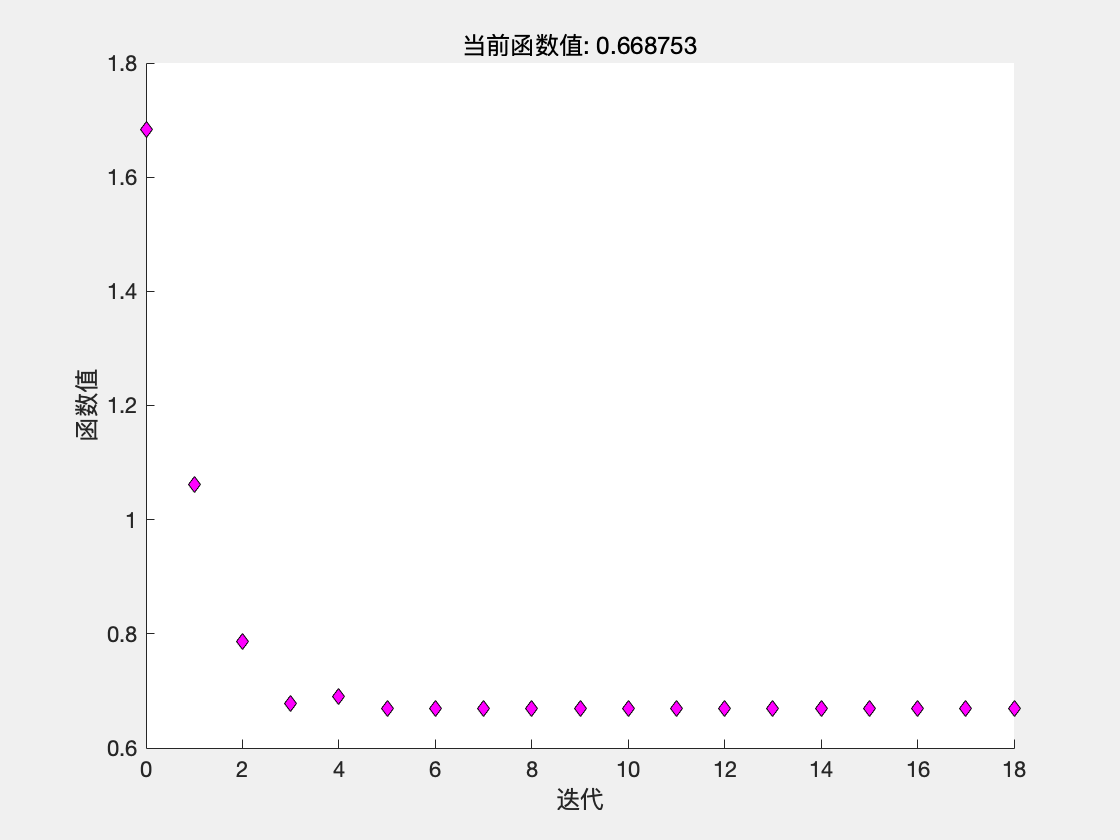

options = optimset('PlotFcns',@optimplotfval,'Display','iter');
VppP_1 = fminbnd(Loss_func_GrapheneTB,1,3,options);

Graphene_single_n = Graphene_single.subs(Graphene_single.symvar_list(1),VppP_1);
EIGENCAR = Graphene_single_n.EIGENCAR_gen();

BAND calculating 60/60 ...


- 使用bandcompare画出能带

bandplot({EIGENCAR_DFT,EIGENCAR} ,[-10,10],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

## 利用MATLAB(2020)控件调整参数 - DFT

- 导入DFT数据

EIGENCAR_DFT = EIGENVAL_read; 

- 引入此近邻

Graphene = Graphene.H_TBSK_gen('level_cut',2); 

Generating Symbolic Hopping term ...< ok >
Setting NRPT 7/7 ...


Graphene.symvar_list

$$ans = \left(\begin{array}{cc} {\mathrm{VppP}}_{1} & {\mathrm{VppP}}_{2} \end{array}\right)$$

- 创建滑块

VppP_1 = 2.7;
VppP_2 = 0.6;
Fermi = 0.1;

- 给TB中的符号化变量赋值

Graphene = Graphene<'KPOINTS';
Graphene_n = Graphene.Subsall();

- 生成能带

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

BAND calculating 60/60 ...


- 使用bandcompare画出能带

bandplot({EIGENCAR_DFT,EIGENCAR} ,[-10,10],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

## 利用NM办法多参数拟合DFT

clear;
EIGENCAR_DFT = EIGENVAL_read; 

generated by phonopy

   1.0

     2.4604399204208875    0.0000000000000000    0.0000000000000000

    -1.2302199602104438    2.1308034755698513    0.0000000000000000

     0.0000000000000000    0.0000000000000000   10.0000000000000000

C

   8

Direct

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C s I

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C p x

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C p y

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C s I

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C p x

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C p y

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C p z 

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C p z

### 创建模型 Script模式

Graphene = HR.from_POSCAR_SE('POSCAR',...
'Type','list',...
'search_range' ,[2 2 0],...
'r_max',2,...
'level_cut',2);

Generating 8/8 th orb nn information ...
Giving nn_level for 96/96 th hopping  ...
Generating Symbolic Hopping term ...< ok >
Setting NRPT 5/5 ...


$$\left(\begin{array}{cccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} \end{array}\right)$$

### 利用MATLAB(2020)控件调整参数 - DFT

E__6_0 = -7;
E__6_1 = 0;
VppP_1 = 2.7;
VppS_1 = -4;
VspS_1 = -4;
VssS_1 = 4;
Fermi  = 0;

Graphene_n = Graphene.Subsall();

- 生成能带

- 画出能带

BAND calculating 60/60 ...


vasplib.bandcompare(Graphene_n.EIGENCAR_gen()-Fermi,EIGENCAR_DFT, [-20,20],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

### NM

#### 拟合参数设置

设定拟合范围：

options_extra.NBAND_range_DFT = [1:4];
options_extra.NBAND_range = [1:4];
options_extra.klist_range = ':';

默认大小和斜率等权

options_extra.weight_list = [1,1];

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

- FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

Graphene_single = subs(Graphene,Graphene.symvar_list(2),0);
Loss_func_TB = @(para) vasplib.loss_func(para, ...
    'FITobj','Graphene',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','pure_comparison' ...
)          

Loss_func_TB = 包含以下值的 function_handle :
    @(para)vasplib.loss_func(para,'FITobj','Graphene','DFTBAND','EIGENCAR_DFT','extra','options_extra','algorithm','pure_comparison')


#### 初值给定

Graphene = Graphene.subs([sym('E__6_1') sym('VppP_1')],[0,2.71353]);
Graphene.symvar_list

$$ans = \left(\begin{array}{cccc} E_{0}^{6} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} \end{array}\right)$$

x0 = [-7,-4,-4,4];

#### 进行拟合

BAND calculating 60/60 ...
 
 Iteration   Func-count     min f(x)         Procedure
     0            1           2.6974         
BAND calculating 60/60 ...
BAND calculating 60/60 ...
BAND calculating 60/60 ...
BAND calculating 60/60 ...
     1            5          2.55176         initial simplex
BAND calculating 60/60 ...
BAND calculating 60/60 ...
     2            7          2.44126         expand
BAND calculating 60/60 ...
     3            8          2.44126         reflect
BAND calculating 60/60 ...
     4            9          2.44126         reflect
BAND calculating 60/60 ...
BAND calculating 60/60 ...
     5           11          2.22082         expand
BAND calculating 60/60 ...
     6           12          2.22082         reflect
BAND calculating 60/60 ...
     7           13          2.22082         reflect
BAND calculating 60/60 ...
BAND calculating 60/60 ...
     8           15          1.95555         expand
BAND calculating 60/60 ...
     9           16          1.95555

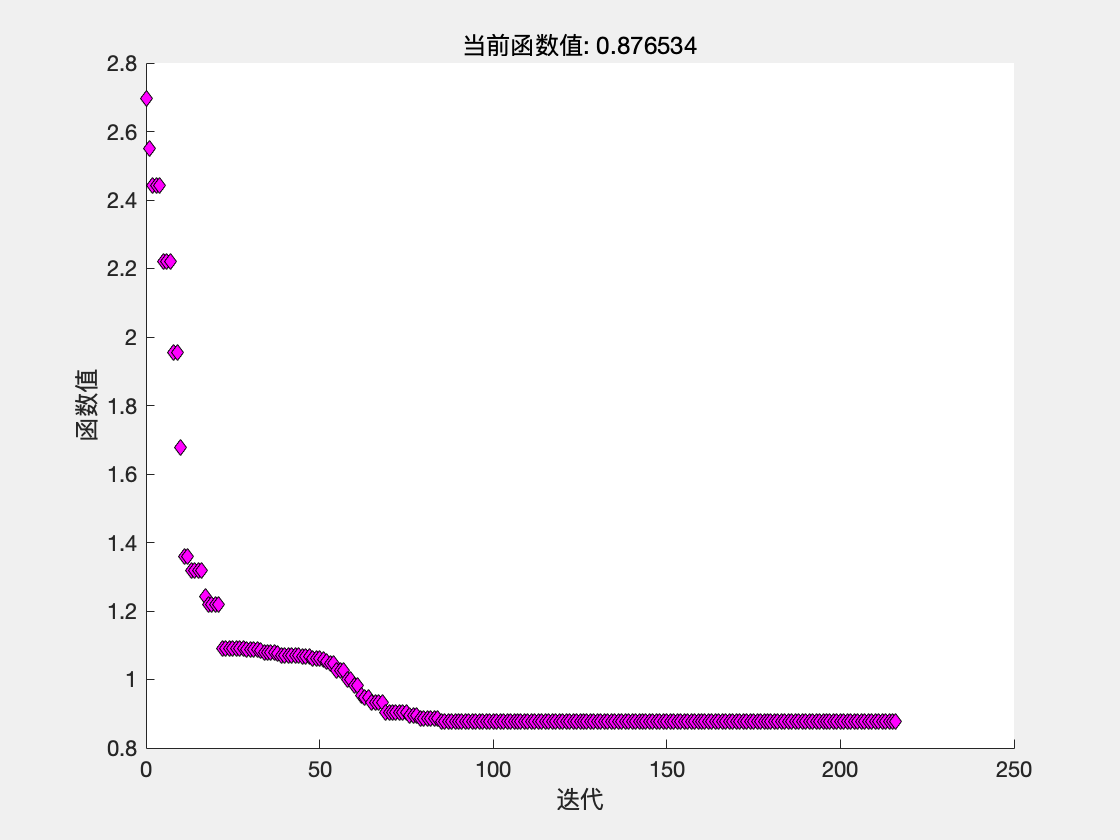

 
优化已终止:
 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件，
F(X) 满足使用 1.000000e-04 的 OPTIONS.TolFun 的收敛条件



options = optimset('PlotFcns',@optimplotfval,'Display','iter');
x = fminsearch(Loss_func_TB,x0,options);

#### 拟合结果

[Graphene_n,EQL] = Graphene.subs(x);
EQL

$$EQL = \left(\begin{array}{cccc} E_{0}^{6}=-4.27945 & {\mathrm{VppS}}_{1}=-4.16767 & {\mathrm{VspS}}_{1}=-9.94658 & {\mathrm{VssS}}_{1}=5.09071 \end{array}\right)$$

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

BAND calculating 60/60 ...


- 画出能带

vasplib.bandcompare(EIGENCAR,EIGENCAR_DFT ,[-20,20],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

## Bayes 拟合（还不完善 慎用）

我们尝试在什么都不知道的情况下拟合能带

开启**delta rule**

Graphene = HR.from_POSCAR_SE('POSCAR',...
'Type','mat',...
'search_range' ,[2 2 0],...
'r_max',4,...
'level_cut',2,...
'deltarule',1);

Generating 8/8 th orb nn information ...
Giving nn_level for 576/576 th hopping  ...
Generating Symbolic Hopping term ...< ok >
Setting NRPT 7/7 ...
applying delta rule ...


$$\left(\begin{array}{ccccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} & \delta \end{array}\right)$$

偶然情况下 我们可以参考 DFT2wannier的结果 (轨道顺序一致) （就没成功过）

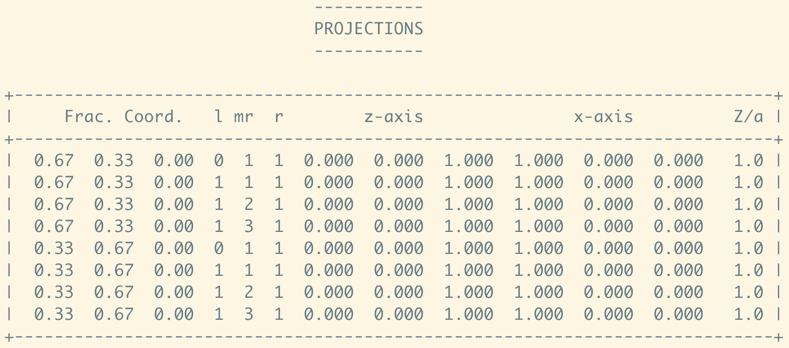

EIGENCAR_DFT = EIGENVAL_read; 
GrapheneWan = HR.from_wannier90()

GrapheneWan =   HR - 属性:

        vectorL: [259×3 double]
          HnumL: [8×8×259 double]
          HcoeL: [0×0 sym]
          NRPTS: 259
        WAN_NUM: 8
       Line_000: 130
      Basis_num: []
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: [1×0 sym]


[VarInit,EQL] =GetInit(Graphene,GrapheneWan,[0,0,0])

VarInit = 包含以下字段的 struct :
    E__6_0: [0×1 sym]
    E__6_1: [0×1 sym]
    VppP_1: [0×1 sym]
    VppS_1: [0×1 sym]
    VspS_1: [0×1 sym]
    VssS_1: [0×1 sym]
     delta: [0×1 sym]


$$EQL = \left(\begin{array}{c} E_{0}^{6}=1.70892\\ E_{1}^{6}=1.6309\\ {\mathrm{VppP}}_{1}=-0.096431+0.049243\,\mathrm{i}\\ {\mathrm{VssS}}_{1}=-0.407131+0.001489\,\mathrm{i}\\ 0.750163\,{\mathrm{VppP}}_{1}+0.249837\,{\mathrm{VppS}}_{1}=0.040467+0.012155\,\mathrm{i}\\ 0.43273\,{\mathrm{VppP}}_{1}-0.43273\,{\mathrm{VppS}}_{1}=4.43472+0.015809\,\mathrm{i}\\ -0.499837\,{\mathrm{VspS}}_{1}=-0.096436-0.049233\,\mathrm{i}\\ 0.499837\,{\mathrm{VspS}}_{1}=-0.00116-0.016351\,\mathrm{i}\\ -0.865742\,{\mathrm{VspS}}_{1}=-0.969337+0.00259\,\mathrm{i}\\ 0.865742\,{\mathrm{VspS}}_{1}=0.006591+0.006483\,\mathrm{i}\\ 0.25049\,{\mathrm{VppP}}_{1}+0.74951\,{\mathrm{VppS}}_{1}=-0.00414+0.024039\,\mathrm{i} \end{array}\right)$$

通过比照


$$E_0^6 =7.41207$$



$$E_1^6 =5.35906$$



$${\textrm{VppP}}_1 =-1.89184$$



$${\textrm{VssS}}_1 =0.346063$$



$${\textrm{VspS}}_1 =4.19456$$



$${\textrm{VppS}}_1 \;\;=\;?$$



$$\delta =?$$


### 构建Bayes 寻参模型

#### 拟合参数设置

设定拟合范围：

options_extra = vasplib.FitOptionHelper(EIGENCAR_DFT,'dirac',...
'Noccu',4,'NBAND_range_DFT',1:4,'highK',[1,20,40,60],'GapThreshold',0.3);    

默认大小和斜率等权

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

-  FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

extra_parm = 0;
Loss_func_TB = @(para,extra_parm) vasplib.loss_func(para,extra_parm, ...
    'FITobj','Graphene',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','dirac' ...
)       

Loss_func_TB = 包含以下值的 function_handle :
    @(para,extra_parm)vasplib.loss_func(para,extra_parm,'FITobj','Graphene','DFTBAND','EIGENCAR_DFT','extra','options_extra','algorithm','dirac')


#### Bayse 模型设置

Varlist = Graphene.symvar_list

$$Varlist = \left(\begin{array}{ccccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} & \delta \end{array}\right)$$

BAND calculating 60/60 ...
|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       E__6_0 |       E__6_1 |       VppP_1 |       VppS_1 |       VspS_1 |       VssS_1 |        delta |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |
|================================================================================================================================================================================|
|    1 | Best   |  2.0044e+20 |      2.2415 |  2.0044e+20 |  2.0044e+20 |       10.923 |       -1.574 |       1.9767 |        4.248 |      -2.2324 |      -1.9957 |    -0.021568 |
BAND calculating 60/60 ...
|    2 | Best   |      8.9404 |      1.6474 |      

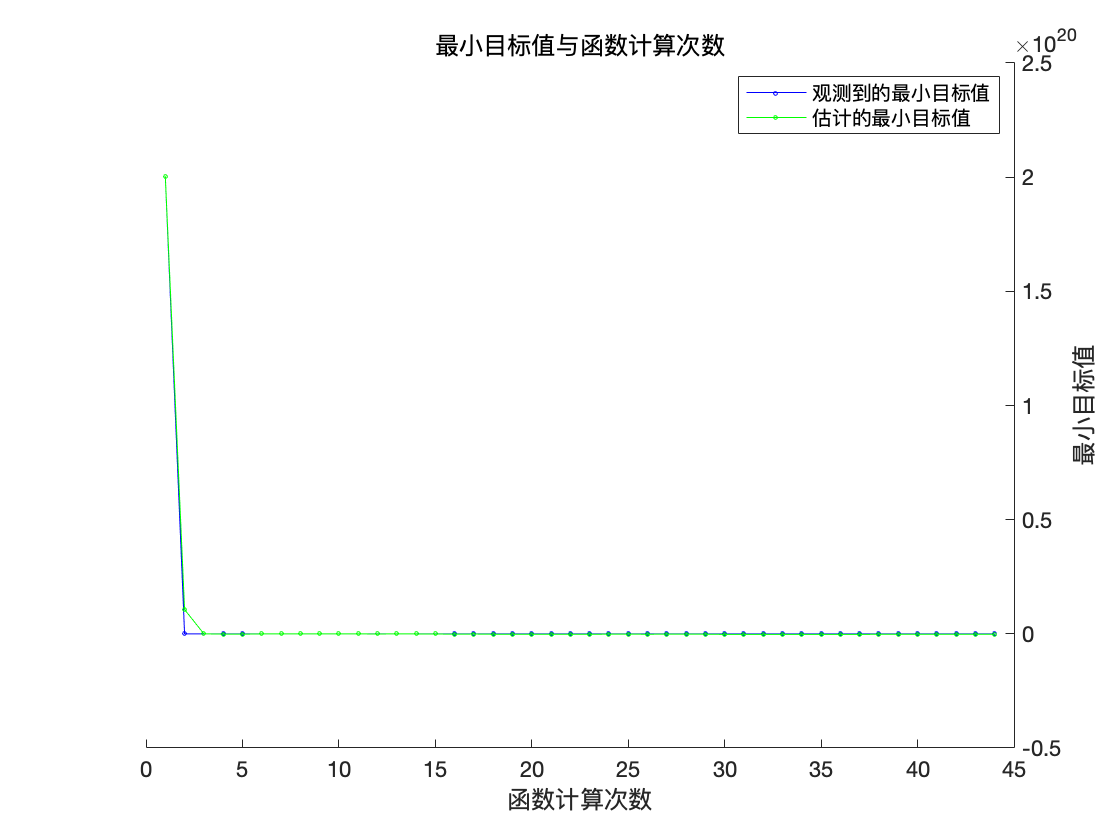


__________________________________________________________
优化完成。
达到 MaxObjectiveEvaluations 44。
函数计算总次数: 44
总历时: 117.9937 秒
总目标函数计算时间: 75.4557

观测到的最佳可行点:
    E__6_0    E__6_1     VppP_1    VppS_1     VspS_1    VssS_1      delta 
    ______    _______    ______    _______    ______    _______    _______

    4.5574    0.26645    2.4728    -1.0909    10.118    -2.0743    0.29414

观测到的目标函数值 = 0.46933
估计的目标函数值 = -8.770221137402266e+16
函数计算时间 = 1.1812

估计的最佳可行点(根据模型):
     E__6_0     E__6_1    VppP_1      VppS_1     VspS_1     VssS_1      delta 
    ________    ______    _______    ________    _______    _______    _______

    0.010373    4.5391    -6.0847    -0.44746    0.69811    -3.8091    0.43453

估计的目标函数值 = -1.699472712761999e+17
估计的函数计算时间 = 1.9707

BAND calculating 60/60 ...
|================================================================================================================================================================================|
| Iter | Eval   | Objective   |

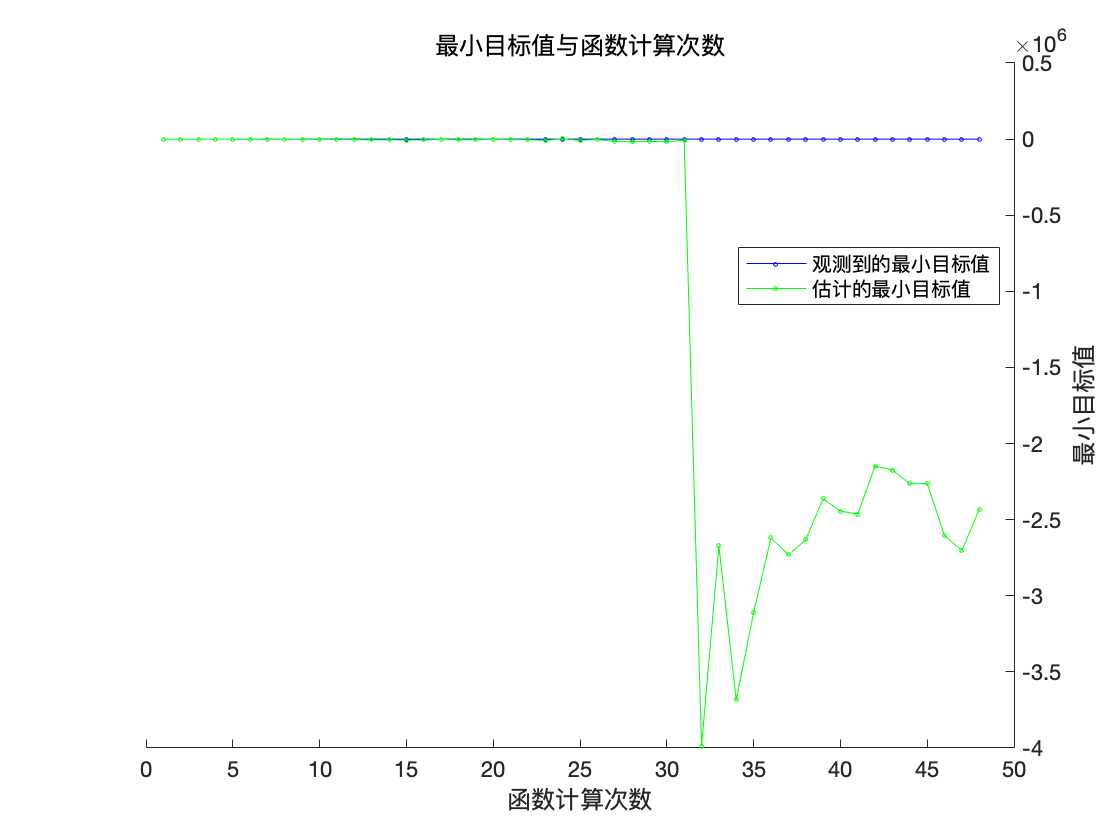


__________________________________________________________
优化完成。
达到 MaxObjectiveEvaluations 48。
函数计算总次数: 48
总历时: 89.1337 秒
总目标函数计算时间: 58.881

观测到的最佳可行点:
    E__6_0     E__6_1    VppP_1     VppS_1     VspS_1     VssS_1      delta 
    _______    ______    _______    _______    _______    _______    _______

    -4.7991    2.6961    -4.1128    -1.5342    0.93635    -4.3017    0.50603

观测到的目标函数值 = 1.2224
估计的目标函数值 = -200722.4491
函数计算时间 = 1.0537

估计的最佳可行点(根据模型):
    E__6_0    E__6_1    VppP_1     VppS_1      VspS_1     VssS_1      delta 
    ______    ______    _______    _______    ________    _______    _______

    1.1826    7.6775    -4.5708    -3.2437    -0.25123    -4.7162    0.17747

估计的目标函数值 = -2431263.8836
估计的函数计算时间 = 1.0556

BAND calculating 60/60 ...
|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoF

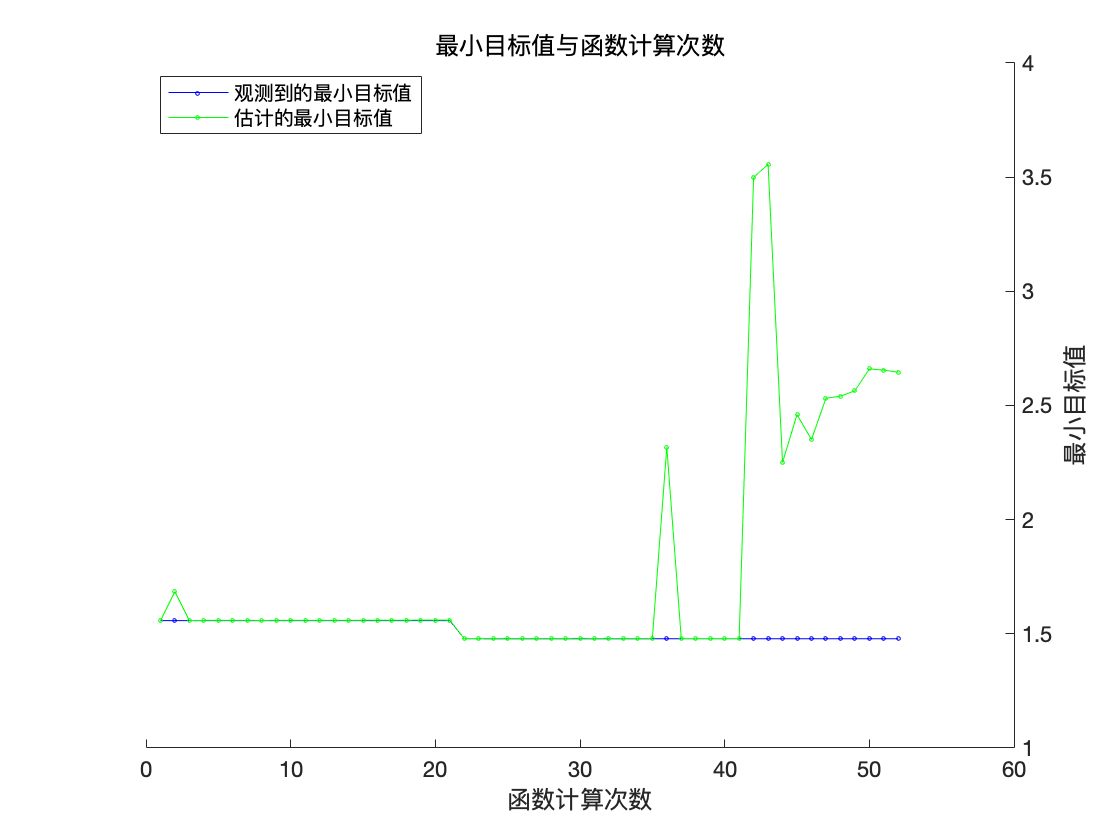


__________________________________________________________
优化完成。
达到 MaxObjectiveEvaluations 52。
函数计算总次数: 52
总历时: 78.5289 秒
总目标函数计算时间: 53.8859

观测到的最佳可行点:
    E__6_0    E__6_1    VppP_1     VppS_1      VspS_1     VssS_1      delta  
    ______    ______    _______    _______    ________    _______    ________

    1.4285    8.8871    -3.9696    -2.4042    -0.34042    -4.4125    0.068524

观测到的目标函数值 = 1.4784
估计的目标函数值 = 3.5671
函数计算时间 = 0.96866

估计的最佳可行点(根据模型):
    E__6_0     E__6_1    VppP_1     VppS_1      VspS_1     VssS_1      delta 
    _______    ______    _______    _______    ________    _______    _______

    0.24684    8.1922    -4.8326    -2.4288    -0.26087    -4.5995    0.12015

估计的目标函数值 = 2.6457
估计的函数计算时间 = 1.0211

BAND calculating 60/60 ...
|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   

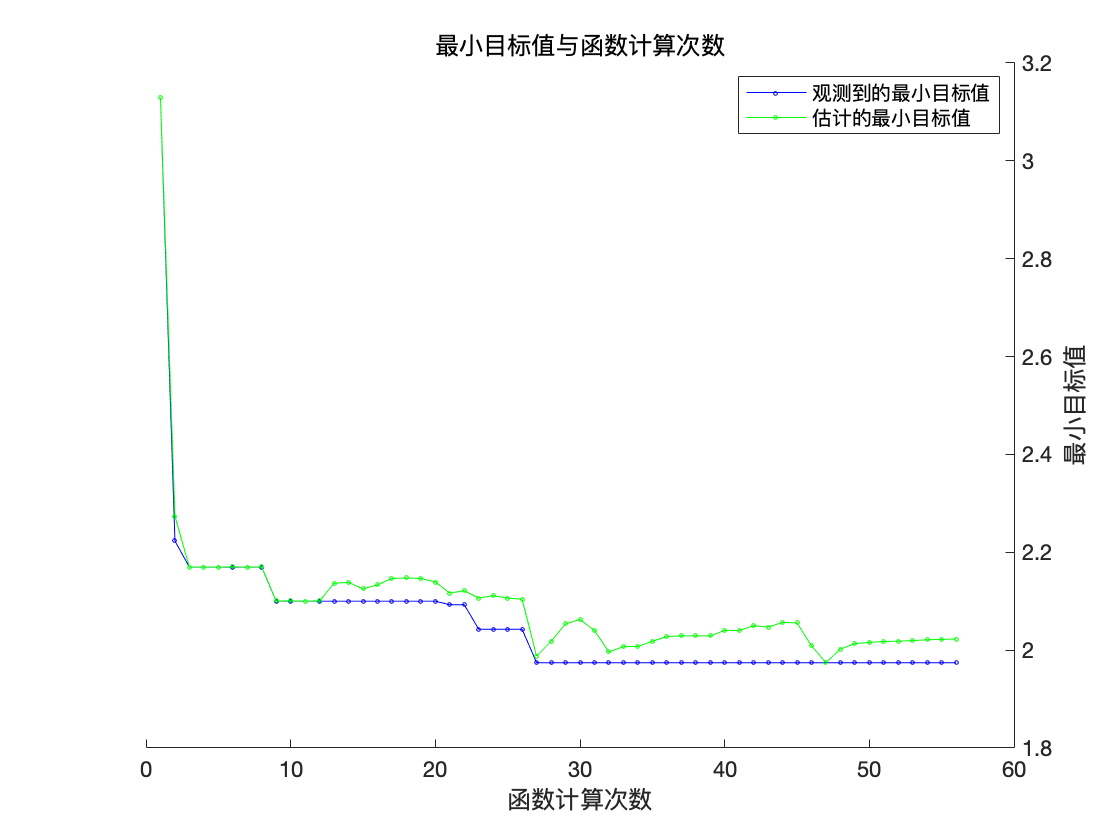


__________________________________________________________
优化完成。
达到 MaxObjectiveEvaluations 56。
函数计算总次数: 56
总历时: 117.4645 秒
总目标函数计算时间: 76.3883

观测到的最佳可行点:
    E__6_0     E__6_1    VppP_1     VppS_1      VspS_1     VssS_1      delta 
    _______    ______    _______    _______    ________    _______    _______

    0.39658    8.0702    -4.9008    -2.5083    -0.20471    -4.4962    0.10673

观测到的目标函数值 = 1.9743
估计的目标函数值 = 2.0227
函数计算时间 = 0.93416

估计的最佳可行点(根据模型):
    E__6_0     E__6_1    VppP_1     VppS_1      VspS_1     VssS_1      delta 
    _______    ______    _______    _______    ________    _______    _______

    0.39658    8.0702    -4.9008    -2.5083    -0.20471    -4.4962    0.10673

估计的目标函数值 = 2.0227
估计的函数计算时间 = 0.93421

BAND calculating 60/60 ...
|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar 

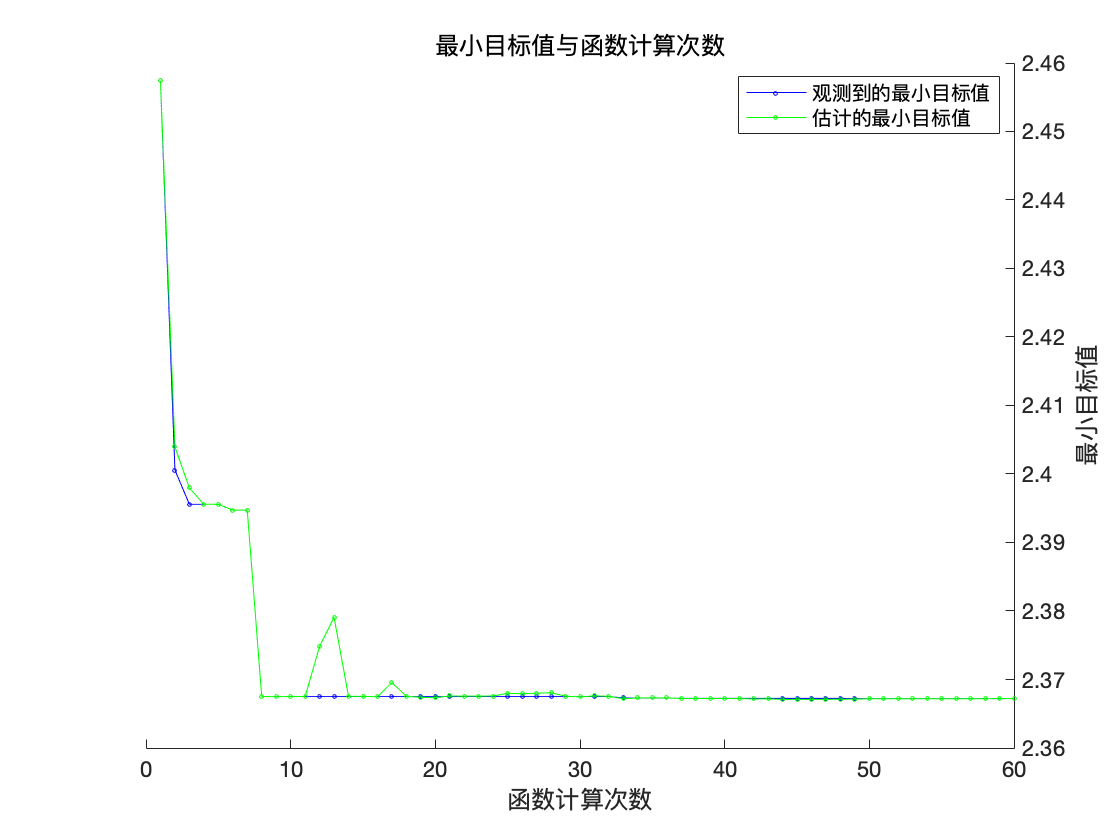


__________________________________________________________
优化完成。
达到 MaxObjectiveEvaluations 60。
函数计算总次数: 60
总历时: 196.5667 秒
总目标函数计算时间: 120.3288

观测到的最佳可行点:
    E__6_0     E__6_1    VppP_1     VppS_1      VspS_1     VssS_1      delta 
    _______    ______    _______    _______    ________    _______    _______

    0.40491    8.0613    -4.9036    -2.5023    -0.20751    -4.4912    0.10763

观测到的目标函数值 = 2.3672
估计的目标函数值 = 2.3672
函数计算时间 = 1.3867

估计的最佳可行点(根据模型):
    E__6_0     E__6_1    VppP_1     VppS_1      VspS_1     VssS_1      delta 
    _______    ______    _______    _______    ________    _______    _______

    0.40491    8.0613    -4.9036    -2.5023    -0.20751    -4.4912    0.10763

估计的目标函数值 = 2.3672
估计的函数计算时间 = 1.3868



VarGuess = [7.41207,5.353906,-1.8901,0.3456,4.19456,0,0];
Varlock  = VarGuess;
VarFix = sym([]);
VarWidth = [10,10,5,7,7,7,1];
fixCriterion = 1e-2;
BayesCycle = 5;
for i = 1 : BayesCycle
    extra_parm = 1-i/BayesCycle;
    Ratio = 0.7 - 0.4*(i /BayesCycle);
    Max_num = 40 + 20*(i /BayesCycle);
    Loss_func = @(parm) Loss_func_TB(parm,extra_parm);
    %
    VarBayes = vasplib.VarBayes(Varlist,VarGuess,VarWidth,VarFix);
    results = bayesopt(Loss_func,VarBayes,'Verbose',1,...
        'AcquisitionFunctionName','expected-improvement-plus',...
        'ExplorationRatio',Ratio,...
        'MaxObjectiveEvaluations',Max_num ...
        );
    %
    VarGuess_nex_time = table2array(results.XAtMinEstimatedObjective);
    Varlock = VarGuess;
    VarWidth = VarWidth/2^i;
    fixVarible = abs(VarGuess_nex_time - VarGuess) < fixCriterion;
    VarFix = Varlist(fixVarible);
    VarGuess = VarGuess_nex_time;
end

[Graphene_n,EQL] = Graphene.subs(VarGuess);
EQL

$$EQL = \left(\begin{array}{ccccccc} E_{0}^{6}=0.404911 & E_{1}^{6}=8.06129 & {\mathrm{VppP}}_{1}=-4.90357 & {\mathrm{VppS}}_{1}=-2.50229 & {\mathrm{VspS}}_{1}=-0.207505 & {\mathrm{VssS}}_{1}=-4.49115 & \delta =0.107633 \end{array}\right)$$

EIGENCAR = Graphene_n.EIGENCAR_gen();

BAND calculating 60/60 ...


- 画出能带

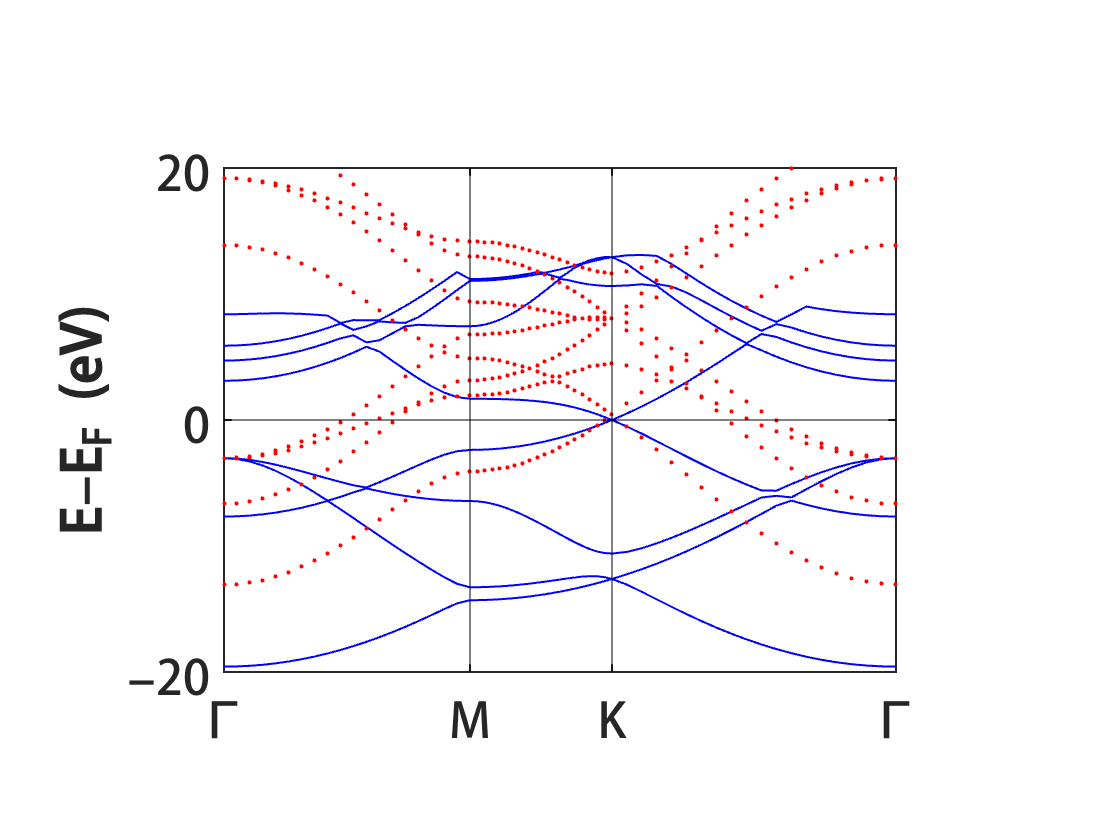

bandcompare(EIGENCAR_DFT,EIGENCAR ,[-20,20]);